## Problem 1

clear;
rng(0);
int_size = 0.1;   %size of the intervals for riemann sum

For each of the following distributions, do: 

- plot the probability density function (PDF) based on the analytical expression. The PDF must appear smooth enough and without apparent signs of discretization.

- plot the cumulative distribution function (CDF) using Riemann-sum approximation. The CDF must appear smooth enough and without apparent signs of discretization. 

- use Riemann-sum approximations to compute the approximate variance (if finite) within a tolerance of 0.01 of its true value known analytically. 

Laplace PDF with location parameter $µ := 2$ and scale parameter $b := 2$.

mu = 2;     % location parameter
b = 2;         % scale parameter

#### PDF

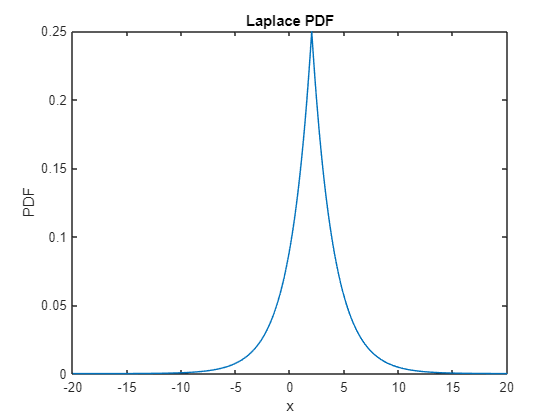

x = -20:int_size:20;    % interval where the PDF is being plotted
y_pdf = (exp(-abs(x-mu)/b))/(2*b);    % Laplace PDF

plot(x, y_pdf), xlabel("x"), ylabel("PDF"), title("Laplace PDF");

#### CDF

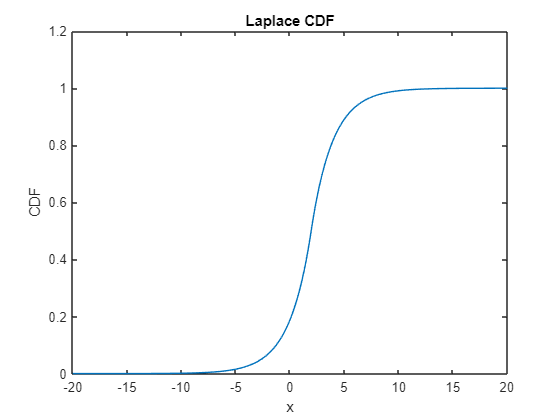

x = -20:int_size:20;    % interval where CDF is being plotted
y_pdf = (exp(-(abs(x-mu))/b))/(2*b);    % Laplace PDF

y_cdf = cumsum(y_pdf)*int_size;   % Laplace CDF

plot(x, y_cdf), xlabel("x"), ylabel("CDF"), title("Laplace CDF");

#### VAR

x = -50:int_size:50;   %interval on which the variance is being calculated(larger interval for accuracy)
y_pdf = (exp(-(abs(x-mu))/b))/(2*b);   % Laplace PDF

mean_2 = sum(x.*x.*y_pdf*int_size);   % E(X^2)
mean = sum(x.*y_pdf*int_size);          %E(X)

var = mean_2 - (mean^2);    % variance calculation
disp(var);

    7.9992



Gumbel PDF  with location parameter $µ := 1$ and scale parameter $\beta  := 2$.

mu = 1;   % location parameter
b = 2;      % scale parameter

#### PDF

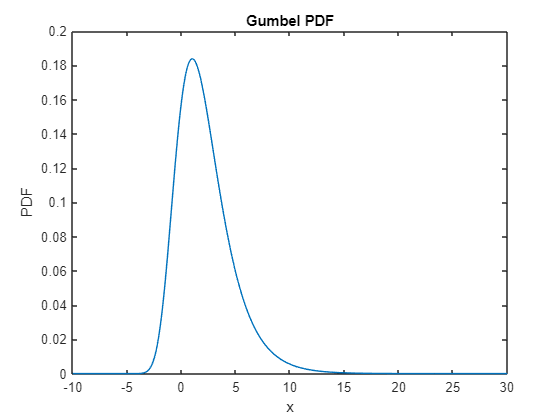

x = -10:int_size:30;    % interval on which PDF is being plotted
z = (x-mu)/b;       
y_pdf = exp(-(z + exp(-z)))/b;    % Gumbel PDF

plot(x, y_pdf), xlabel("x"), ylabel("PDF"), title("Gumbel PDF");

#### CDF

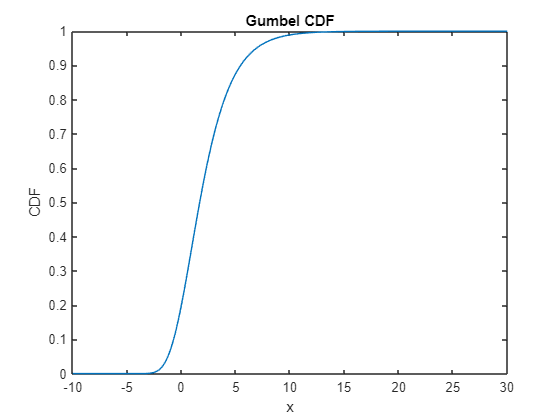

y_cdf = cumsum(y_pdf)*int_size;    % Gumbel CDF

plot(x, y_cdf), xlabel("x"), ylabel("CDF"), title("Gumbel CDF");  

#### VAR

x = -20:int_size:40;   % interval on which variance is being calculated
z = (x-mu)/b;
y_pdf = exp(-(z + exp(-z)))/b;   % Gumbel PDF

mean_2 = sum(x.*x.*y_pdf*int_size);   % E(X^2)
mean = sum(x.*y_pdf*int_size);      % E(X)

var = mean_2 - (mean^2);   % variance of gumbel distribution
disp(var);

    6.5797



Cauchy PDF with location parameter $x_0 := 0$ and scale parameter $\gamma  := 1$. 

x_0 = 0;     % location parameter
gam = 1;    % scale parameter

#### PDF

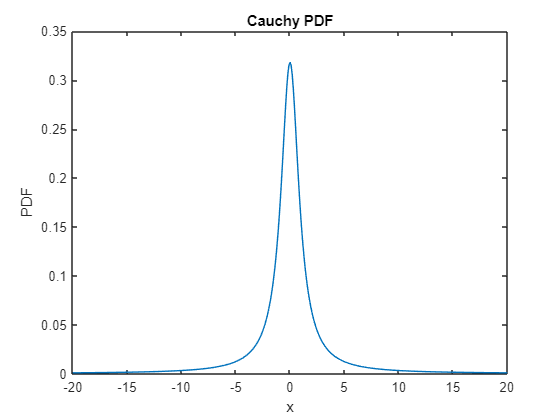

x = -20:int_size:20;  % interval on which PDF is being plotted
z = 1+((x-x_0)/gam).^2;     
y_pdf = 1./(pi*gam*z);      % Cauchy PDF

plot(x, y_pdf), xlabel("x"), ylabel("PDF"), title("Cauchy PDF");

#### CDF

y_cdf = cumsum(y_pdf)*int_size;   % Cauchy CDF

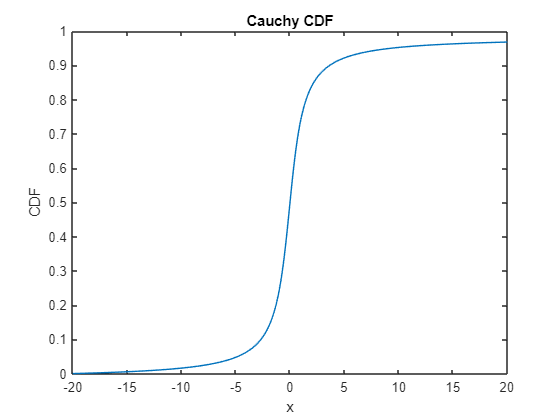


plot(x, y_cdf), xlabel("x"), ylabel("CDF"), title("Cauchy CDF");

#### Variance:

Cauchy distribution is a diverging distribution. It's variance is not defined